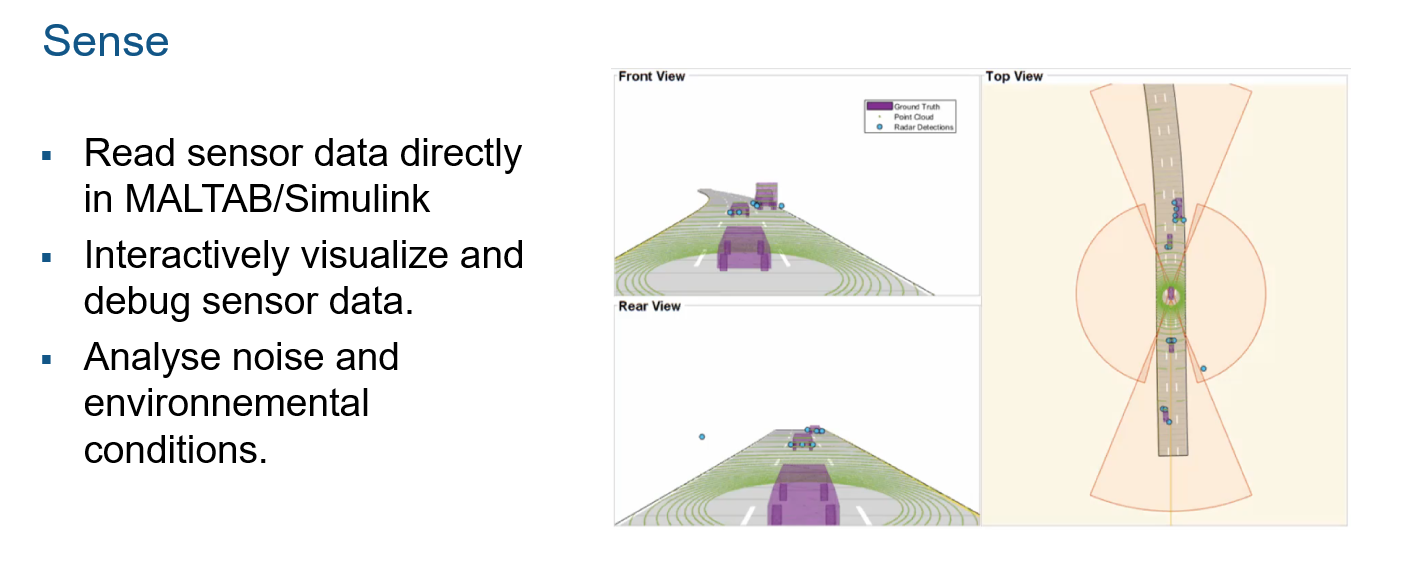

## Connecting MATLAB/Simulink to ROS

`rosinit` starts the global ROS node with a default MATLAB® name and tries to connect to a ROS master running on `localhost` and port `11311`. If the global ROS node cannot connect to the ROS master, `rosinit` also starts a ROS core in MATLAB, which consists of a ROS master, a ROS parameter server, and a rosout logging node.

rosshutdown

Shutting down global node /matlab_global_node_04866 with NodeURI http://192.168.137.1:57011/


rosinit 192.168.137.134

Initializing global node /matlab_global_node_07413 with NodeURI http://192.168.137.1:50976/


%rosinit 192.168.1.127

## Initialize Subscriber

Use `rossubscriber` to create a ROS subscriber for receiving messages on the ROS network. To send messages, use `rospublisher`. To wait for a new ROS message, use the [`receive`](https://www.mathworks.com/help/ros/ref/receive.html) function with your created subscriber.

laserSub = rossubscriber('/scan');
laserdata = receive(laserSub,1)

laserdata =   ROS LaserScan message with properties:

       MessageType: 'sensor_msgs/LaserScan'
            Header: [1×1 Header]
          AngleMin: -2.3562
          AngleMax: 2.3562
    AngleIncrement: 0.0044
     TimeIncrement: 0
          ScanTime: 0
          RangeMin: 0.1000
          RangeMax: 10
            Ranges: [1081×1 single]
       Intensities: [1081×1 single]

  Use showdetails to show the contents of the message


## Interactively visualize data

`plot(`[`scanMsg`](https://www.mathworks.com/help/ros/ref/plot.html#buqbjtl-scan)`)` plots the laser scan readings specified in the input [`LaserScan`](https://www.mathworks.com/help/ros/ref/laserscan.html) object message. Axes are automatically scaled to the maximum range that the laser scanner supports. When plotting ROS laser scan messages, MATLAB® follows the standard ROS convention for axis orientation. This convention states that **positive *****x***** is forward, positive *****y *****is left, and positive *****z***** is up**.

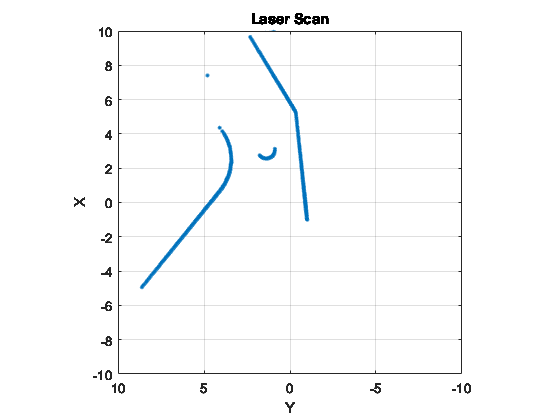

fgh = figure(); % create a figure
axh = axes('Parent',fgh); % create axes
lnh = plot(laserdata); % plot in those axes

rate = rateControl(10);

while rate.TotalElapsedTime < 5
laserdata = receive(laserSub,1);
axh = axes('Parent',fgh);
lnh = plot(laserdata);
waitfor(rate);
end

## Initialize Publisher

[velPub, velMsg] = rospublisher('/vesc/high_level/ackermann_cmd_mux/input/nav_0');
velMsg.Drive.Speed = 0;
velMsg.Drive.Acceleration = 0.01;
velMsg.Drive.Jerk = 0.01;
velMsg.Drive.SteeringAngle = 0;
velMsg.Drive.SteeringAngleVelocity = 0.3;


## Initialize VFH controller

vfh = controllerVFH;
vfh.UseLidarScan = true;
vfh.DistanceLimits = [0.2 3];
vfh.RobotRadius = 0.1;
vfh.MinTurningRadius = 0.3;
vfh.SafetyDistance = 0.15;

rate = rateControl(10);


while rate.TotalElapsedTime < 300
       
        targetDir = 0;
	
        % Get laser scan data
	laserScan = receive(laserSub);        
	ranges = double(laserScan.Ranges);
	angles = double(laserScan.readScanAngles);
                 
	% Create a lidarScan object from the ranges and angles
        scan = lidarScan(ranges,angles);
        
	% Call VFH object to computer steering direction
	steerDir = vfh(scan, targetDir)
    
	% Calculate velocities
	if ~isnan(steerDir) % If steering direction is valid
                desiredV = 2;
                w = exampleHelperComputeAngularVelocity(steerDir, 5);
	else % Stop and search for valid direction
		desiredV = -1;
		w = 0;
                pause(1);
	end

	% Assign and send velocity commands
	velMsg.Drive.Speed = desiredV;
	velMsg.Drive.SteeringAngle = w;
	send(velPub,velMsg);
        %show(vfh)
        
end

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4873

steerDir = 0.4712

steerDir = 0.4363

steerDir = 0.4014

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0.2793

steerDir = 0.2793

steerDir = 0.2793

steerDir = 0.2618

steerDir = 0.2618

steerDir = 0.2618

steerDir = 0.2618

steerDir = 0.2618

steerDir = 0.2443

steerDir = 0.2443

steerDir = 0.2443

steerDir = 0.2269

steerDir = 0.2269

steerDir = 0.2269

steerDir = 0.2094

steerDir = 0.2094

steerDir = 0.1920

steerDir = 0.1920

steerDir = 0.1745

steerDir = 0.1745

steerDir = 0.1745

steerDir = 0.1571

steerDir = 0.1571

steerDir = 0.1396

steerDir = 0.1222

steerDir = 0.1222

steerDir = 0.1047

steerDir = 0.1047

steerDir = 0.1047

steerDir = 0.1047

steerDir = 0.0873

steerDir = 0.0873

steerDir = 0.0873

steerDir = 0.0873

steerDir = 0.0698

steerDir = 0.0698

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0.0349

steerDir = 0.0349

steerDir = 0.0349

steerDir = 0.0349

steerDir = 0.0175

steerDir = 0.0175

steerDir = 0.0175

steerDir = 0.0175

steerDir = 0.0175

steerDir = 1.4647

steerDir = 1.4647

steerDir = 1.4647

steerDir = 1.4647

steerDir = 1.4647

steerDir = 1.4647

steerDir = 1.4647

steerDir = 1.4647

steerDir = 1.4647

steerDir = 1.4297

steerDir = 1.4297

steerDir = 1.4297

steerDir = 1.3948

steerDir = 1.3599

steerDir = 1.3250

steerDir = 1.3250

steerDir = 1.2901

steerDir = 1.2901

steerDir = 1.2552

steerDir = 1.2552

steerDir = 1.2203

steerDir = 1.2203

steerDir = 1.1854

steerDir = 1.1854

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1156

steerDir = 1.1156

steerDir = 1.1156

steerDir = NaN

steerDir = NaN

steerDir = NaN

steerDir = -2.7402

steerDir = -2.7402

steerDir = -2.7402

steerDir = -2.7402

steerDir = -2.7402

steerDir = -2.7402

steerDir = -2.7402

steerDir = -2.7402

steerDir = -2.7402

steerDir = -2.7402

steerDir = -2.7213

steerDir = -2.7213

steerDir = -2.7213

steerDir = -2.6864

steerDir = -2.6515

steerDir = -2.6515

steerDir = -2.6166

steerDir = -2.6166

steerDir = -2.5817

steerDir = -2.5468

steerDir = -2.5118

steerDir = -2.4769

steerDir = -2.4420

steerDir = -2.4420

steerDir = -2.4071

steerDir = -2.3722

steerDir = -2.3373

steerDir = -2.3024

steerDir = -2.2675

steerDir = -2.2326

steerDir = -2.1977

steerDir = -2.1628

steerDir = -2.1279

steerDir = -2.0930

steerDir = -2.0581

steerDir = -2.0232

steerDir = -1.9882

steerDir = -1.9533

steerDir = -1.9184

steerDir = -1.8835

steerDir = -1.8486

steerDir = -1.8137

steerDir = -1.7439

steerDir = -1.7090

steerDir = -1.6392

steerDir = -1.6043

steerDir = -1.5345

steerDir = -1.4996

steerDir = -1.4647

steerDir = -1.3948

steerDir = -1.3250

steerDir = -1.2901

steerDir = -1.2203

steerDir = -1.1854

steerDir = -1.1505

steerDir = -1.0807

steerDir = -1.0458

steerDir = -1.0109

steerDir = -0.9760

steerDir = -0.9760

steerDir = -0.9061

steerDir = -0.8712

steerDir = -0.8363

steerDir = -0.7665

steerDir = -0.7316

steerDir = -0.6967

steerDir = -0.6618

steerDir = -0.5920

steerDir = -0.5571

steerDir = -0.5222

steerDir = -0.4524

steerDir = -0.4175

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0.3316

steerDir = 0.3316

steerDir = 0.3316

steerDir = 0.3316

steerDir = 0.3316

steerDir = 0.3316

steerDir = 0.3316

steerDir = 0.3316

steerDir = 0.3316

steerDir = 0.3316

steerDir = 0.3316

steerDir = 0.3316

steerDir = 0.3316

steerDir = 0.3142

steerDir = 0.2967

steerDir = 0.2793

steerDir = 0.2793

steerDir = 0.2443

steerDir = 0.2443

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0.4175

steerDir = 0.4175

steerDir = 0.4175

steerDir = 0.4175

steerDir = 0.4175

steerDir = 0.4175

steerDir = 0.4175

steerDir = 0.4175

steerDir = 0.4175

steerDir = 0.4175

steerDir = 0.4175

steerDir = 0.4175

steerDir = 0.4175

steerDir = 0.4175

steerDir = 0.4175

steerDir = 0.4175

steerDir = 0.4175

steerDir = 0.4175

steerDir = 0.4175

steerDir = 0.4014

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0.0175

steerDir = 0.0175

steerDir = 0.0175

steerDir = 0.0175

steerDir = 1.3599

steerDir = 1.3599

steerDir = 1.3599

steerDir = 1.3599

steerDir = 1.3599

steerDir = 1.3599

steerDir = 1.3599

steerDir = 1.3599

steerDir = 1.3599

steerDir = 1.3599

steerDir = 1.3250

steerDir = 1.3250

steerDir = 1.2901

steerDir = 1.2552

steerDir = 1.2552

steerDir = 1.2203

steerDir = 1.2203

steerDir = 1.1854

steerDir = 1.1505

steerDir = 1.1156

steerDir = 1.0807

steerDir = 1.0458

steerDir = 1.0458

steerDir = 1.0109

steerDir = 1.0109

steerDir = 0.9760

steerDir = 0.9411

steerDir = 0.9061

steerDir = 0.8712

steerDir = 0.8363

steerDir = 0.8363

steerDir = 0.8014

steerDir = 0.7665

steerDir = 0.7316

steerDir = 0.6967

steerDir = 0.6618

steerDir = 0.4014

steerDir = 0.3316

steerDir = 0.3142

steerDir = 0.2618

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = -0.5411

steerDir = -0.5411

steerDir = -0.5411

steerDir = -0.5411

steerDir = -0.5411

steerDir = -0.5411

steerDir = -0.5411

steerDir = -0.6632

steerDir = -0.6632

steerDir = -0.6632

steerDir = -0.7505

steerDir = -0.7505

steerDir = -0.7505

steerDir = -0.8029

steerDir = -0.8029

steerDir = -0.8203

steerDir = -0.8203

steerDir = 1.1156

steerDir = 1.1156

steerDir = 1.1156

steerDir = 1.1156

steerDir = 1.1156

steerDir = 1.1156

steerDir = 1.1156

steerDir = 1.1156

steerDir = 1.1156

steerDir = 1.1156

steerDir = 1.1156

steerDir = 1.1156

steerDir = 1.1156

steerDir = 1.1156

steerDir = 1.1156

steerDir = 1.1156

steerDir = 1.1156

steerDir = 1.1156

steerDir = 1.0807

steerDir = 1.0807

steerDir = 1.0458

steerDir = 1.0458

steerDir = 1.0109

steerDir = 1.0109

steerDir = 0.9760

steerDir = 0.9760

steerDir = 0.9411

steerDir = 0.9411

steerDir = 0.9061

steerDir = 0.9061

steerDir = 0.8712

steerDir = 0.8712

steerDir = 0.8363

steerDir = 0.8363

steerDir = 0.8363

steerDir = 0.8363

steerDir = 0.8014

steerDir = 0.8014

steerDir = 0.7665

steerDir = 0.7665

steerDir = 0.7665

steerDir = 0.7665

steerDir = 0.7316

steerDir = 0.7316

steerDir = 0.6967

steerDir = 0.6967

steerDir = 0.6967

steerDir = 0.6967

steerDir = 0.6618

steerDir = 0.6618

steerDir = 0.6618

steerDir = 0.6269

steerDir = 0.6269

steerDir = 0.6269

steerDir = 0.6269

steerDir = 0.6269

steerDir = 0.5920

steerDir = 0.5920

steerDir = 0.5571

steerDir = 0.5061

steerDir = 0.4887

steerDir = 0.4538

steerDir = 0.4189

steerDir = 0.3840

steerDir = 0.3665

steerDir = 0.3316

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = -0.2967

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

%Stop  
velMsg.Drive.Speed = 0;
velMsg.Drive.SteeringAngle = 0;
send(velPub,velMsg)